clear all
load ARTEMIS.mat;
start=100;%Definisci l'istante iniziale
N=5; %Time horizon
u=[];
for j=1:18
    %Estrai i sottovettori
    speed=ARTEMIS(1,start-1+j*N:start+N-1+j*N);
    acceleration=ARTEMIS(2,start-1+j*N:start+N-1+j*N);
    gear=ARTEMIS(3,start-1+j*N:start+N-1+j*N);
    StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
    
    %Definisci l'handle della funzione di update dello stato
    FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
    tic
    opts=optimoptions('fmincon','algorithm','sqp','MaxFunctionEvaluations',1e5,'Display','none');
    u=[u;fmincon(FullStateUpdate,0.5*ones(N,1),[],[],[],[],-1*ones(N,1),ones(N,1),[],opts)];
    toc
end

Elapsed time is 1.660391 seconds.
Elapsed time is 0.623221 seconds.
Elapsed time is 0.742600 seconds.
Elapsed time is 0.881258 seconds.
Elapsed time is 0.777255 seconds.
Elapsed time is 0.669235 seconds.
Elapsed time is 0.283587 seconds.
Elapsed time is 0.870147 seconds.
Elapsed time is 0.025146 seconds.
Elapsed time is 0.772684 seconds.
Elapsed time is 0.404518 seconds.
Elapsed time is 1.645116 seconds.
Elapsed time is 1.075798 seconds.
Elapsed time is 1.869274 seconds.
Elapsed time is 0.830662 seconds.
Elapsed time is 0.021086 seconds.
Elapsed time is 0.032224 seconds.
Elapsed time is 0.022608 seconds.


speed=ARTEMIS(1,start:end);
acceleration=ARTEMIS(2,start:end);
gear=ARTEMIS(3,start:end);
StateUpdate=@(input,cur_SOC,i)hev_MPC(speed(i),acceleration(i),gear(i),cur_SOC,input);
%Definisci l'handle della funzione di update dello stato
FullStateUpdate=@(u)full_horizon(u,0.55,StateUpdate);
[cost,I,SOC,mf]=FullStateUpdate(u);
sum(mf)

ans = 0.0021

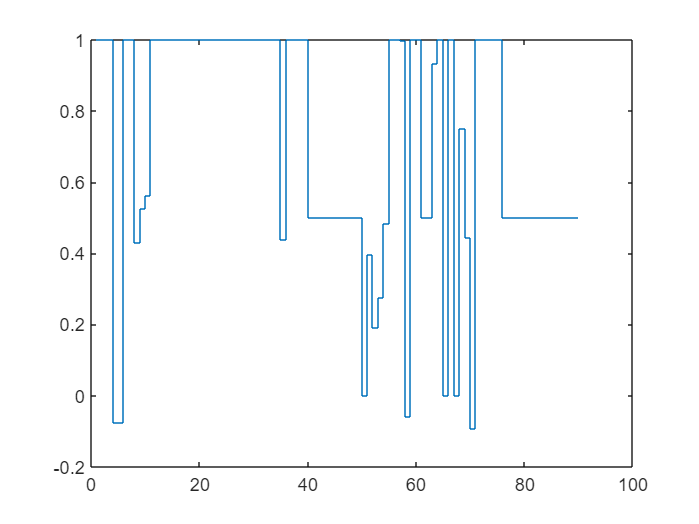

stairs(u)

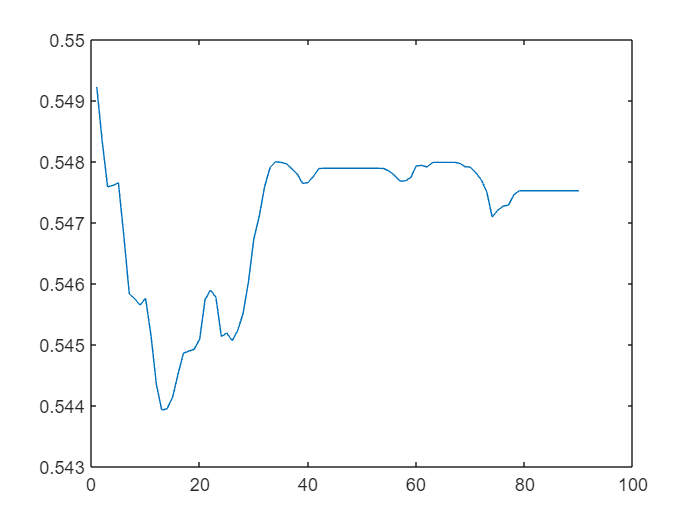

plot(SOC)

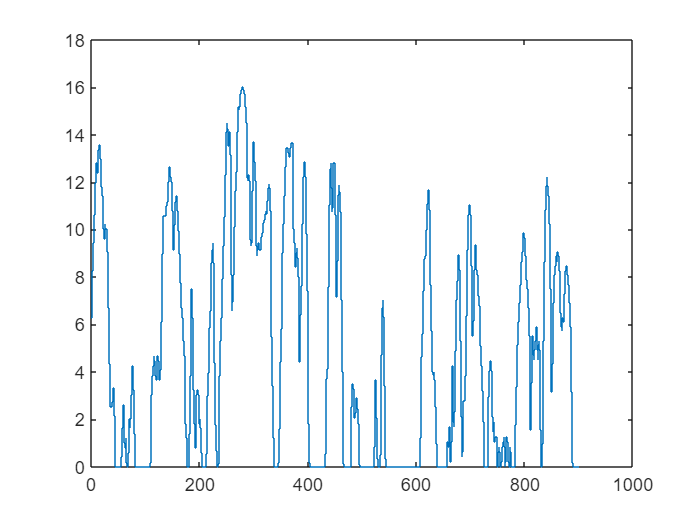

stairs(speed)

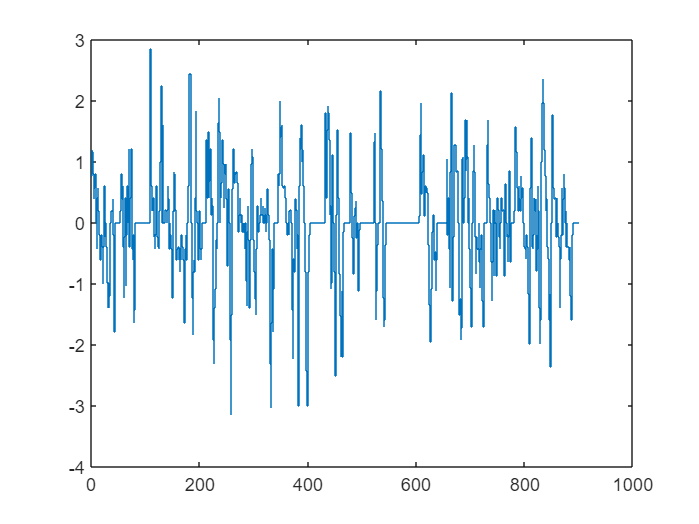

stairs(acceleration)